## Metabolic Modelling Introduction 

Authors : Hugues Escoffier & Maria Pires Pacheco

#### Creation of a Toy Model

**Model : **

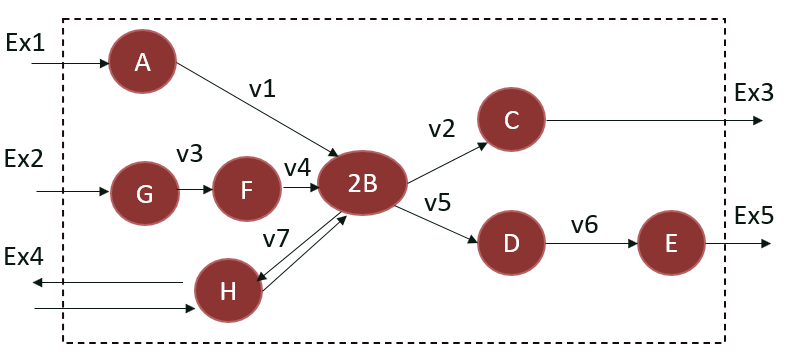

clear

%Create Model
ReactionFormulas = {'A -> 2 B','2 B -> C', 'G -> F','F -> 2 B', '2 B -> D','D -> E', ...
                    'H <=> 2 B', '-> A', '-> G', 'C ->', '<=> H', 'E ->'};
ReactionNames = {'v1','v2','v3', 'v4', 'v5', 'v6', 'v7', 'Ex1','Ex2','Ex3','Ex4','Ex5'};
GeneNames={'Gene1','Gene2','Gene3', 'Gene4', 'Gene5', 'Gene6','Gene7','GeneEx1', 'GeneEx2', 'GeneEx3', 'GeneEx4', 'GeneEx5'};
model = createModel(ReactionNames, ReactionNames, ReactionFormulas,'grRuleList',GeneNames);

**In the case of the Recon3D model, by convention, all exchange reactions are defined as exports and reversible. **

For example, in this model the exchange reaction ' -> G' becomes by convention 'G <=>'.

%Create Model as Recon3D
ReactionFormulas = {'A -> 2 B','2 B -> C', 'G -> F','F -> 2 B', '2 B -> D','D -> E', ...
                    'H <=> 2 B', 'A <=>', 'G <=>', 'C ->', 'H <=>', 'E ->'};
ReactionNames = {'v1','v2','v3', 'v4', 'v5', 'v6', 'v7', 'Ex1','Ex2','Ex3','Ex4','Ex5'};
GeneNames={'Gene1','Gene2','Gene3', 'Gene4', 'Gene5', 'Gene6','Gene7','GeneEx1', 'GeneEx2', 'GeneEx3', 'GeneEx4', 'GeneEx5'};
model = createModel(ReactionNames, ReactionNames, ReactionFormulas,'grRuleList',GeneNames);

% (Facultative) Visualize the model

disp('S') ; full(model.S) %S Matrix
disp('mets') ; model.mets %Metabolites 
disp('rxns') ; model.rxns %Reactions
disp('boundaries') ; disp([model.rxns num2cell(model.lb) num2cell(model.ub)]) %Upper & Lower boundaries for each reactions
disp('genes') ; disp(model.genes)

#### Model Consistency Verification

Model consistency means that each reaction is capable of carrying a non-zero flow. This is achieved by eliminating dead-ends and gaps.

A = fastcc_4_rfastcormics(model, 1e-4, 0); % Check if the model is consistent
% if not :
% consistent_model = removeRxns(model, model.rxns(setdiff(1:numel(model.rxns),A))) 

#### Exchange Reactions and Medium Constraints

Exchange reactions are reactions that link the system to the extracellular environment represented by the reactions leaving the recangle in the toy model. 

To match reality, we want the model to be able to exchange only with the metabolites present in the medium (A in this example).

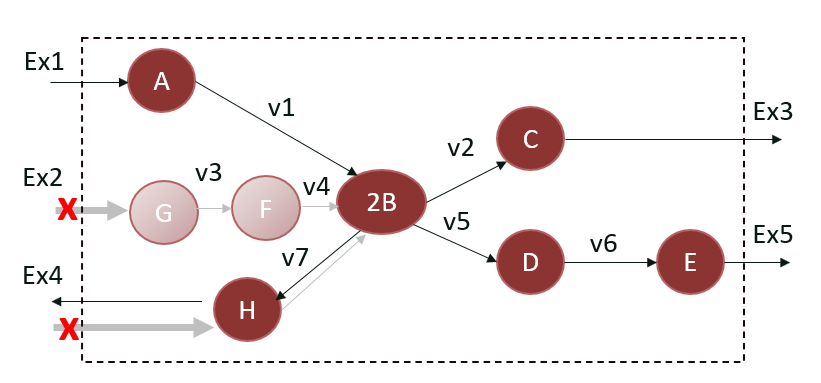

medium = {'A[c]'} % Create the medium containing only the metabolite 'A[c]'
[EX] = findExcRxns(model); % Find all exchange reactions
printRxnFormula(model, model.rxns(find(EX))); % Shows all exchange reactions
[Ex_open] = findRxnsFromMets(model, medium)
Ex_to_close=setdiff(model.rxns(EX),Ex_open) % Find the reactions that should be unable to carry a flux

**For the 'classically defined' model **

medium_model = model; % Save in case of mistake

for i = 1:length(Ex_to_close) % For each reactions to close
     var = nonzeros(medium_model.S(:,ismember(medium_model.rxns,Ex_to_close(i)))); % Return +1 if the reaction is an import / -1 if it is an export
     if var > 0 % Import
         medium_model.ub(ismember(medium_model.rxns,Ex_to_close(i))) = 0; % Close the upper bound (cannot receive a flux anymore)
     else % if var < 0 (Export)
         medium_model.lb(ismember(medium_model.rxns,Ex_to_close(i))) = 0; % Close the lower bound (cannot send a flux)
     end
end

disp('boundaries') ; disp([medium_model.rxns num2cell(medium_model.lb) num2cell(medium_model.ub)]) % New Upper & Lower boundaries for each reactions

**For the Recon3D-like model**

medium_model = model; % Save in case of mistake
medium_model.lb(ismember(medium_model.rxns,Ex_to_close)) = 0

Indeed, all exchange relations are defined as reversible exports, so blocking imports is achieved by closing the lower bound of each of these reactions. 

**/!\** This case is only valid in the case of a model where the exchange relationships are defined in the Recon3D way. The general case is described above 

% Create a consistent model constrained by the metabolites present in the model 
A = fastcc_4_rfastcormics(medium_model, 1e-4, 0);
medium_constrained_consistent_model=removeRxns(medium_model,medium_model.rxns(setdiff(1:numel(medium_model.rxns),A)))

% (Facultative) Visualize Model

disp('S') ; full(medium_constrained_consistent_model.S) %S Matrix
disp('mets') ; medium_constrained_consistent_model.mets %Metabolites 
disp('rxns') ; medium_constrained_consistent_model.rxns %Reactions
disp('boundaries') ; disp([medium_constrained_consistent_model.rxns num2cell(medium_constrained_consistent_model.lb) num2cell(medium_constrained_consistent_model.ub)]) %Upper & Lower boundaries for each reactions
disp('genes') ; disp(medium_constrained_consistent_model.genes)
printRxnFormula(medium_constrained_consistent_model)

**Consistent model after adding the condition on the medium : **

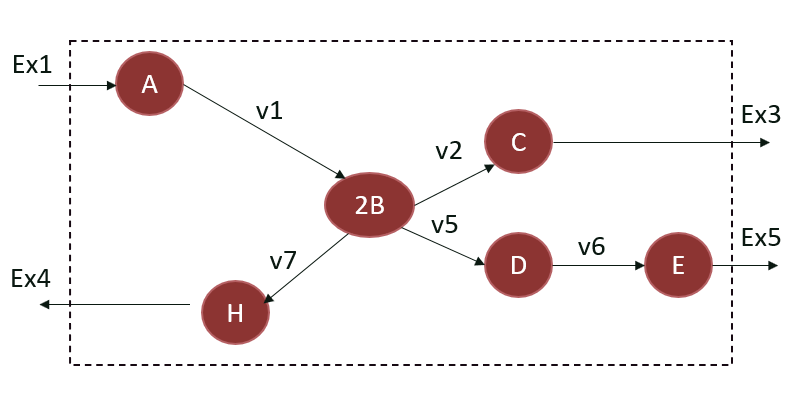

#### Introduction to Fastcormics : Integration of core reactions

• A **Core reactions** correspond to reactions supported by the data are forced to carry a flux above epsilon (small positive value) by an approximation of the cardinality function

• **Non Core reactions**: the inclusion of reactions not supported by the data is minimized by a L1-regularization (the inclusion on non-core reactions is penalized so that only non core reactions that are required to allow core reactions to be consistent are included)

In this example :

- Core reactions (*forced to carry a flux*) : **Ex3, v7**

- Inactive reaction (*do not carry a flux*) :  **v2**

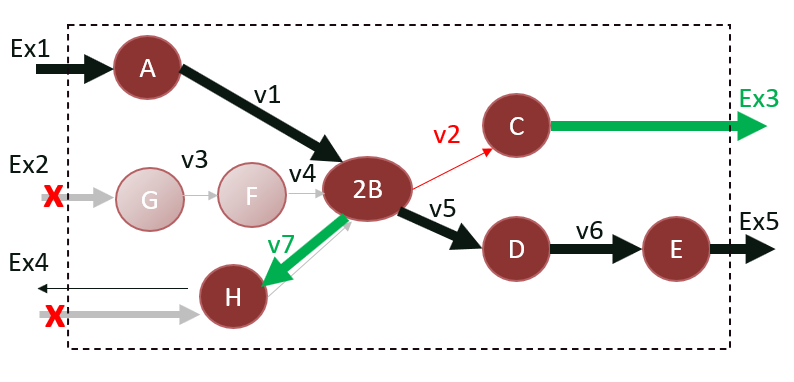

**Using Fastcormics : **

fastcormics_RNAseq(model, data, rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optinal_settings)

- **model **: Model use to extract the context-specific model from

- **data** : Matrix with *n* rows (1 per rxns) and *m* columns (1 per sample) with 1 for expressed genes, 0 for unknown expression and -1 for unexpressed genes. 

- **rownames** : The gene names for each row in the data

- **dico** :  Dictionary to map the gene names to the gene names in the model (e.g. Entrez to EnsemblID)

- **biomass_rxn **: Rxn that is (*generally*) to be maximized

- **already_mapped_tag** :  0 if the data has not been mapped to the GPR rules of the model, 1 otherwise

- **consensus_proportion** :  In the case where several samples are used to reconstruct a model

- **epsilon** :  Flux threshold value (1e-4)

- **optional_settings **: Structure containing 4 elements.

**Optional_settings : **

- **unpenalized** : Matrix containing the rxns that should not be penalized during model creation. These reactions are chosen above the others, even though they are not part of the core reactions. 

- **func** : Rxns that are (*generally*) to be maximized and must be retained

- **not_medium_constrained** : Rxns not included in the medium that must be retained

- **medium** : Metabolites present in the medium

discritized = [0;-1;0;0;0;0;1;0;0;1;0;0]; % For this model, we create a matrix based on the information in the description.
rownames = medium_constrained_consistent_model.genes;
dico = table(medium_constrained_consistent_model.genes, medium_constrained_consistent_model.genes);
biomass_rxn = 'Ex5'; % In this example we want to maximize 'Ex5'
already_mapped_tag = 0;
consensus_proportion = 1;
epsilon = 1e-4;
% Optional settings 
optional_settings = struct;
optional_settings.unpenalized = {};
optional_settings.func = {'Ex5'};
optional_settings.not_medium_constrained = {};
% optional_settings.medium = medium; % ERROR metFormulas

#### Creation of the 'Medium & Core Constrained Consistent Model' 

To create a model from the A_final array, we will create a logical matrix with the samples as columns and the reactions as rows in which 1 depicts if a reaction should take place in the context-specific model.

% run Fastcormics_RNAseq 
[medium_core_constrained_consistent_model, ~] = fastcormics_RNAseq(medium_constrained_consistent_model, discritized, rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optional_settings)

**Medium & Core Constrained Consistent Model : **

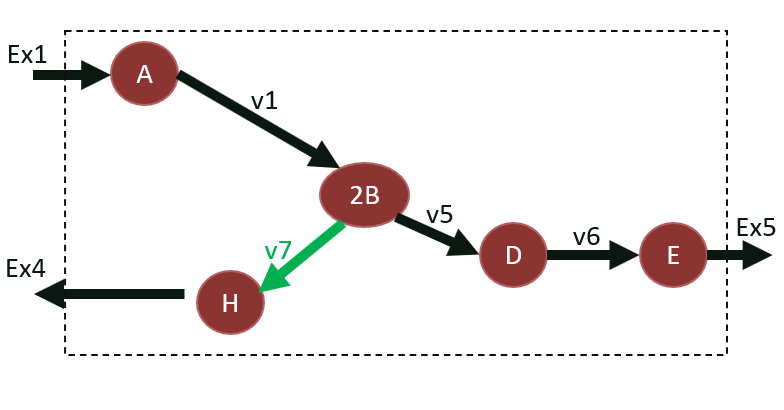

% (Facultative) Visualize Model

disp('S') ; full(medium_core_constrained_consistent_model.S) %S Matrix
disp('mets') ; medium_core_constrained_consistent_model.mets %Metabolites 
disp('rxns') ; medium_core_constrained_consistent_model.rxns %Reactions
disp('boundaries') ; disp([medium_core_constrained_consistent_model.rxns num2cell(medium_core_constrained_consistent_model.lb) num2cell(medium_core_constrained_consistent_model.ub)]) %Upper & Lower boundaries for each reactions
disp('genes') ; disp(medium_core_constrained_consistent_model.genes)
printRxnFormula(medium_core_constrained_consistent_model)

#### Objective and optimisation of the Model

We set an objective function in the model. In this example we have decided to maximize the rxn 'Ex5'

index_objective_rxn = find(ismember(medium_core_constrained_consistent_model.rxns, 'Ex5')); % Find the index of the 'Ex5' rxn
medium_core_constrained_consistent_model = changeObjective(medium_core_constrained_consistent_model,medium_core_constrained_consistent_model.rxns(index_objective_rxn)); % Change the objective function 
printObjective(medium_core_constrained_consistent_model) % Check the change 

We can now optimize the model to get the maximal value through the 'v5' rxn.

changeCobraSolver('ibm_cplex');
solution = optimizeCbModel(medium_core_constrained_consistent_model,'max') 

The solution.f field give the maximal value of the flux through the objective function. 